T = table;
for n = 2:13
    x = ones(n, 1);
    H = hilb(n);
    b = H * x;
    x_hat = H \ b;
    
    f_n = log10(10^(1.49044545*(n)-1.72));
    condition_number = log10(cond(H));
    
    relative_error = norm(x_hat - x, inf)/norm(x, inf);
    g_n = -log10(cond(H)) + 16.5941;
    logrr = -log10(relative_error);
    
    T = [T; table(n, f_n, condition_number, relative_error, g_n, logrr)];
end

disp(T)

    n      f_n      condition_number    relative_error      g_n       logrr  
    __    ______    ________________    ______________    _______    ________

     2    1.2609         1.2851           7.7716e-16       15.309      15.109
     3    2.7513         2.7194           7.4385e-15       13.875      14.129
     4    4.2418         4.1907           4.5053e-13       12.403      12.346
     5    5.7322         5.6782           3.9924e-12       10.916      11.399
     6    7.2227         7.1747            5.724e-10       9.4194      9.2423
     7    8.7131          8.677            2.019e-08       7.9171      7.6949
     8    10.204         10.183           3.7286e-07       6.4106      6.4285
     9    11.694         11.693           1.3105e-05       4.9011      4.8825
    10    13.18

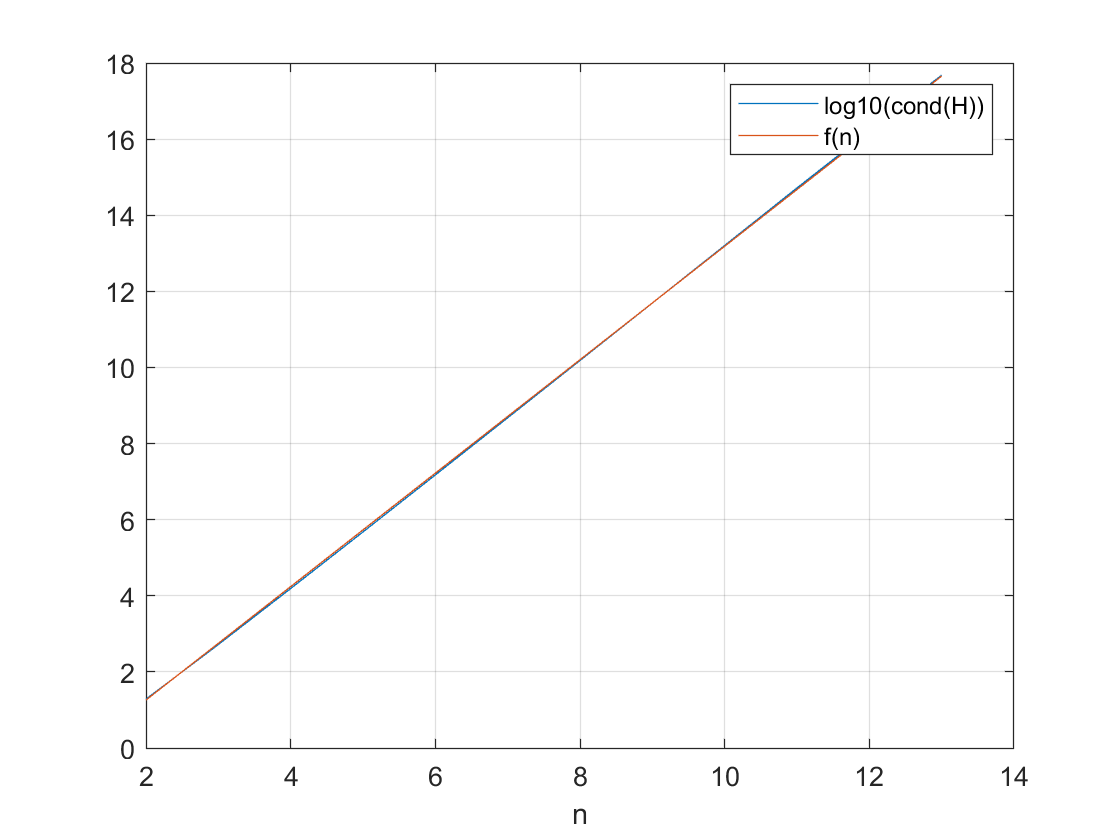

plot(T.n, T.condition_number, T.n, T.f_n), xlabel('n'), legend('log10(cond(H))', 'f(n)'), grid on

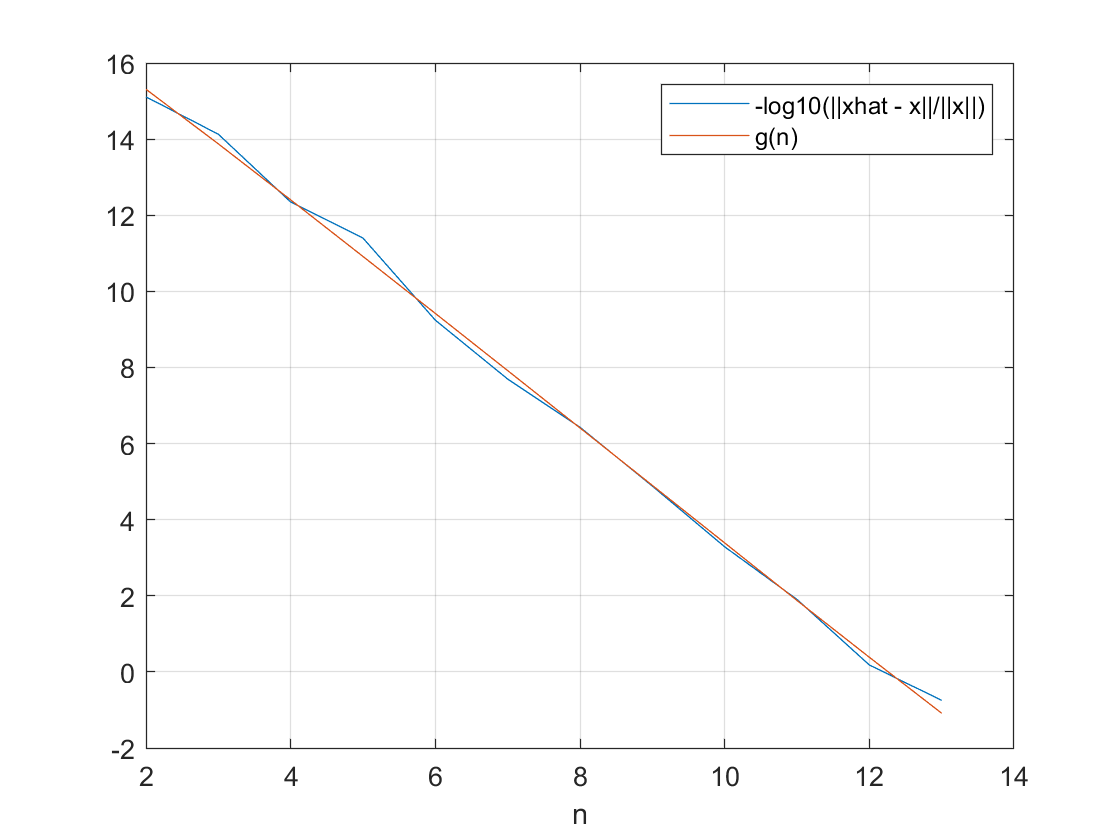

plot(T.n, T.logrr, T.n, T.g_n), xlabel('n'), legend('-log10(||xhat - x||/||x||)', 'g(n)'), grid on